# Problem 1

F = @(x) [x(1)^3 + 3*x(2)^2 - 21;
          x(1)^2 + 2*x(2) + 2];

J = @(x) [3*x(1)^2, 6*x(2);
          2*x(1),   2];

x = [1; -1];
epsilon = 1e-6;
max_iter = 100;
iter = 0;

while true
    Fx = F(x);
    Jx = J(x);
    
    delta = -Jx \ Fx;
    x_new = x + delta;
    
    if norm(delta, inf) < epsilon
        break;
    end
    
    x = x_new;
    iter = iter + 1;
    
    if iter > max_iter
        error('Maximum iterations exceeded');
    end
end

fprintf('Solution found after %d iterations:\n', iter);

Solution found after 5 iterations:


disp(x_new);

    1.6430
   -2.3498



## Problem 2

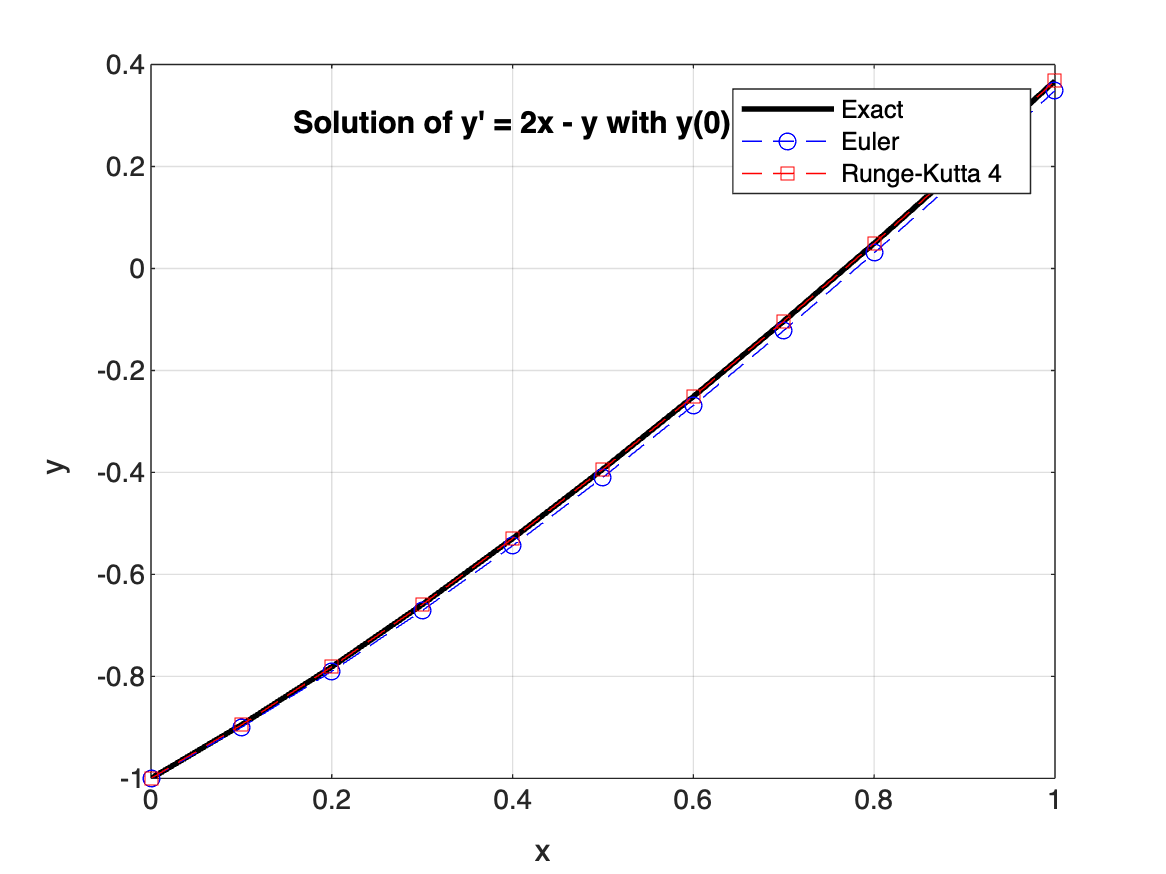

f = @(x, y) 2*x - y;

a = 0;
b = 1;
N = 10;
h = (b - a) / N;

x = linspace(a, b, N+1);
y_euler = zeros(1, N+1);
y_rk4 = zeros(1, N+1);
y_exact = exp(-x) + 2*x - 2;

y_euler(1) = -1;
y_rk4(1) = -1;

for i = 1:N
    y_euler(i+1) = y_euler(i) + h * f(x(i), y_euler(i));
end

for i = 1:N
    k1 = f(x(i), y_rk4(i));
    k2 = f(x(i) + h/2, y_rk4(i) + h*k1/2);
    k3 = f(x(i) + h/2, y_rk4(i) + h*k2/2);
    k4 = f(x(i) + h, y_rk4(i) + h*k3);
    
    y_rk4(i+1) = y_rk4(i) + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
end

plot(x, y_exact, 'k-', 'LineWidth', 2); hold on;
plot(x, y_euler, 'bo--', 'DisplayName', 'Euler');
plot(x, y_rk4, 'rs--', 'DisplayName', 'Runge-Kutta 4');
legend('Exact', 'Euler', 'Runge-Kutta 4');
xlabel('x'); ylabel('y');
title('Solution of y'' = 2x - y with y(0) = -1');
grid on;